close all, clear all
%construction of the matrix
N=20;
A1=zeros(N);
for i=1:N
    for j=1:N
        if (i==j+1 || i==j-1)
        A1(i,j)=-1;
        end
    end
end
A1(1,length(A1))=-1;
A1(length(A1),1)=-1;
A1

A1 =      0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   

%looking for maximum eigenvalue in norme
[eigvectmin,eigvalmin]=eig_power(A1)

eigvectmin =    -0.2236
   -0.2236
   -0.2236
   -0.2236
   -0.2236
   -0.2236
   -0.2236
   -0.2236
   -0.2236
   -0.2236


eigvalmin = -2


[eigvectmax,eigvalmax]=eig_ipower(A1,2)

eigvectmax =    -0.2236
    0.2236
   -0.2236
    0.2236
   -0.2236
    0.2236
   -0.2236
    0.2236
   -0.2236
    0.2236


eigvalmax = 2

%verification
eig(A1)

ans =    -2.0000
   -1.9021
   -1.9021
   -1.6180
   -1.6180
   -1.1756
   -1.1756
   -0.6180
   -0.6180
   -0.0000


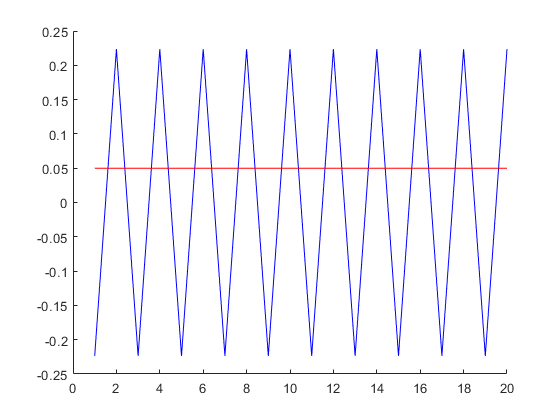

figure(1)
hold on
plot(1:N,eigvectmax,'b')
plot(1:N,eigvectmax.^2,'r')

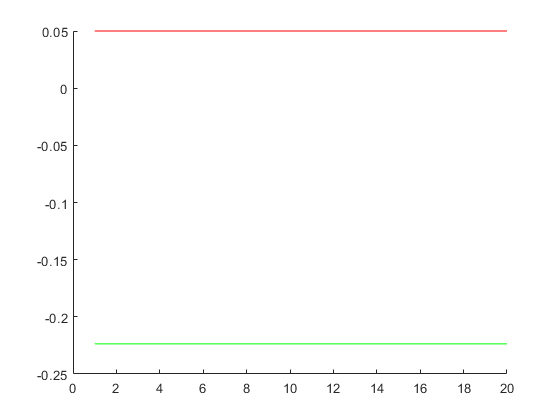

figure(2)
hold on
plot(1:N,eigvectmin,'g')
plot(1:N,eigvectmin.^2,'r')

close all, clear all
%construction of matrix
N=21;
A2=zeros(N);
for i=1:N
    for j=1:N
        if (i==j+1 || i==j-1)
        A2(i,j)=-1;
        end
    end
end
A2(1,length(A2))=-1;
A2(length(A2),1)=-1;
A2

A2 =      0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0    

%looking for eigenvalues
[eigvectmin,eigvalmin]=eig_power(A2)

eigvectmin =    -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182


eigvalmin = -2.0000

[eigvectmax,eigvalmax]=eig_ipower(A2,1.977)

eigvectmax =    -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182
   -0.2182


eigvalmax = -2.0000

eig(A2)

ans =    -2.0000
   -1.9111
   -1.9111
   -1.6525
   -1.6525
   -1.2470
   -1.2470
   -0.7307
   -0.7307
   -0.1495


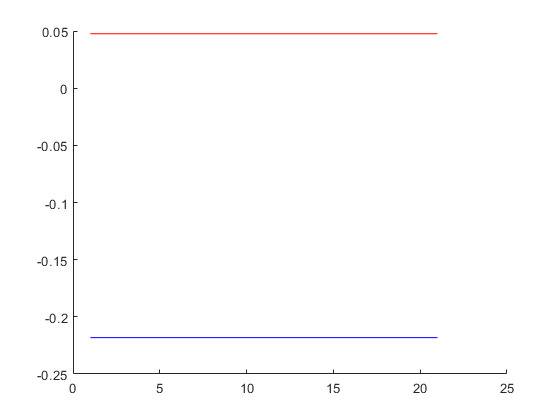

figure(1)
hold on
plot(1:N,eigvectmax,'b')
plot(1:N,eigvectmax.^2,'r')

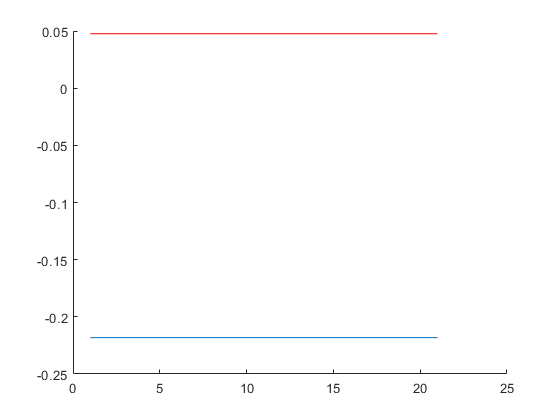

figure(2)
hold on
plot(1:N,eigvectmin)
plot(1:N,eigvectmin.^2,'r')